#  Investigate the distribution of the OLS and MLE on AR models.

Investigating the distribution of **OLS** (Ordinary Least Squares) and **MLE** (Maximum Likelihood Estimator) in **Autoregressive (AR)** models allows us to understand how these estimators behave under repeated sampling, and how close their empirical properties are to the theoretical ones.

In an AR(p) model,

## 
$$\[
y_t = \phi_1 y_{t-1} + \phi_2 y_{t-2} + \cdots + \phi_p y_{t-p} + \varepsilon_t,
\quad \varepsilon_t \sim \mathcal{N}(0, \sigma^2)
\]$$


both OLS and MLE can be used to estimate the parameters $\Phi_i$. Under the assumption of normally distributed errors, **OLS and MLE are asymptotically equivalent** — they yield the same point estimates for large samples. However, when the sample size is small, or when the noise is not normally distributed, their finite-sample distributions may differ.

Through **Monte Carlo simulation**, we can repeatedly generate artificial data from a known AR process and compute the OLS and MLE estimates each time. By plotting their histograms and calculating empirical means and variances, we can approximate their **sampling distributions**. This reveals several key insights:

- As the **sample size N** increases, both estimators become more tightly distributed around the true parameter values (their variance decreases).

- The **sampling distribution** of both estimators becomes increasingly **normal-shaped** as predicted by the **asymptotic normality** theory.

- For small samples, **OLS may remain unbiased but less efficient**, while **MLE tends to have smaller variance** but can show slight bias, especially if the normality assumption is not satisfied.

- Comparing both estimators helps to illustrate the trade-off between **efficiency** (smaller variance) and **robustness** (less sensitivity to distributional assumptions).

Reflecting on this problem emphasizes the importance of understanding **sampling variability** rather than relying solely on single estimates. It also shows how simulation complements theoretical results by making the statistical properties of estimators visible and intuitive.

## Investigate the distribution of OLS and MLE estimators calculating the Monte Carlo density, empirical cumulative distribution and bias for the following AR models:

#### 
$$\[
y_t = 0.5\,y_{t-1} + \varepsilon_t
\]

\[
y_t = 0.5\,y_{t-1} - 0.3\,y_{t-2} + 0.6\,y_{t-3} + \varepsilon_t
\]

\[
y_t = 1.2\,y_{t-1} - 0.5\,y_{t-2} - 0.3\,y_{t-3} + 0.4\,y_{t-4} - 0.2\,y_{t-5} + \varepsilon_t
\]
$$


In all cases consider $\varepsilon_t \sim NIID\,(0,1)$

%% Monte Carlo: OLS vs MLE in AR(p)
% eps_t ~ N(0,1). Compare distributions of estimators.
rng(1);

% --- Settings ---
N  = 50;      % sample size per replication
R  = 100;       % Monte Carlo replications
arp = [1.2, -0.5, -0.3, 0.4, -0.2];   % <-- choose one:
% arp = 0.5;                         % AR(1)
% arp = [0.5, -0.3, 0.6];            % AR(3)
% arp = [1.2, -0.5, -0.3, 0.4, -0.2];% AR(5) (non-stationary)

p = numel(arp);
fprintf('AR(%d) with phi = [%s]\n', p, num2str(arp));

AR(5) with phi = [1.2        -0.5        -0.3         0.4        -0.2]



% quick stationarity check (roots outside unit circle)
polycoefs = [1, -arp];
if any(abs(roots(polycoefs))<=1)
    warning('This AR is non-stationary (roots on/inside unit circle). MLE may fail or behave poorly.');
end


% Storage (just AR coefficients, like your R code)
MCest_OLS = nan(R, p);
MCest_MLE = nan(R, p);

% Detect Econometrics Toolbox for MLE
hasET = ~isempty(ver('econ'));

%% Monte Carlo loop
for i = 1:R
    % --- simulate AR(p) with zero constant, eps ~ N(0,1) ---
    y = simulate_ar(arp, 1, N, 500);   % burn-in = 500
    
    % --- OLS (conditional least squares, no intercept) ---
    MCest_OLS(i, :) = ar_ols_phi_only(y, p);
    
    % --- MLE (Gaussian exact ML), if available ---
    if hasET
        try
            mdl = arima('Constant', 0, 'ARLags', 1:p, 'Variance', NaN); % Constant fixed at 0
            est = estimate(mdl, y, 'Display', 'off');
            phi_mle = cell2mat(est.AR);        % 1-by-p
            MCest_MLE(i, :) = phi_mle;
        catch
            % leave NaNs if estimation fails
        end
    end
    
    if mod(i,10)==0 || i==1
        fprintf('Now done replication %d out of %d\n', i, R);
    end
end

Now done replication 1 out of 100
Now done replication 10 out of 100
Now done replication 20 out of 100
Now done replication 30 out of 100
Now done replication 40 out of 100
Now done replication 50 out of 100
Now done replication 60 out of 100
Now done replication 70 out of 100
Now done replication 80 out of 100
Now done replication 90 out of 100
Now done replication 100 out of 100


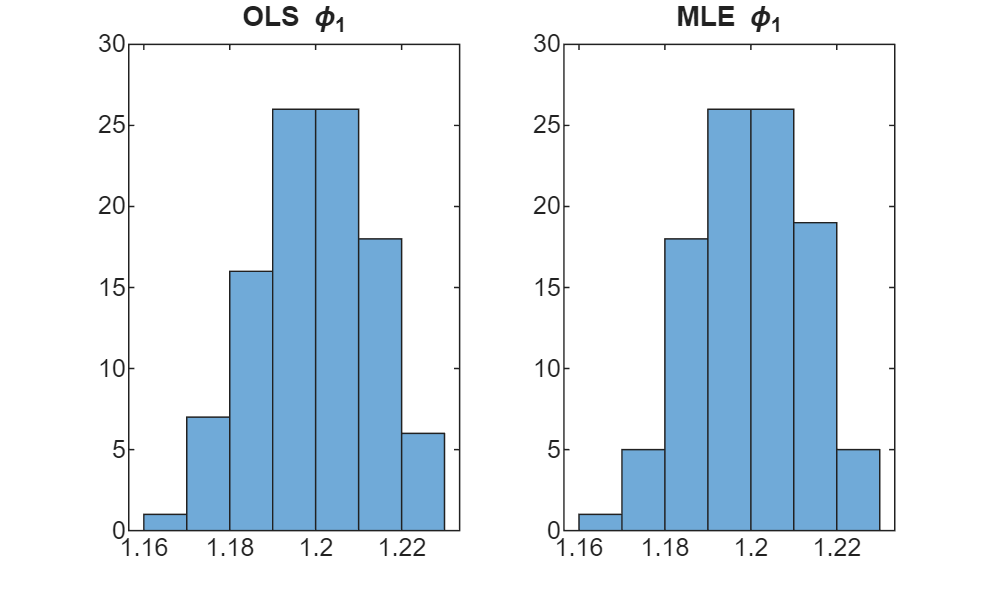


%% Choose parameter index to inspect
ip = 1;    % 1..p

%% Histograms
figure;
subplot(1,2,1), histogram(MCest_OLS(:,ip)), title(sprintf('OLS \\phi_%d',ip))
subplot(1,2,2), histogram(MCest_MLE(:,ip)), title(sprintf('MLE \\phi_%d',ip))

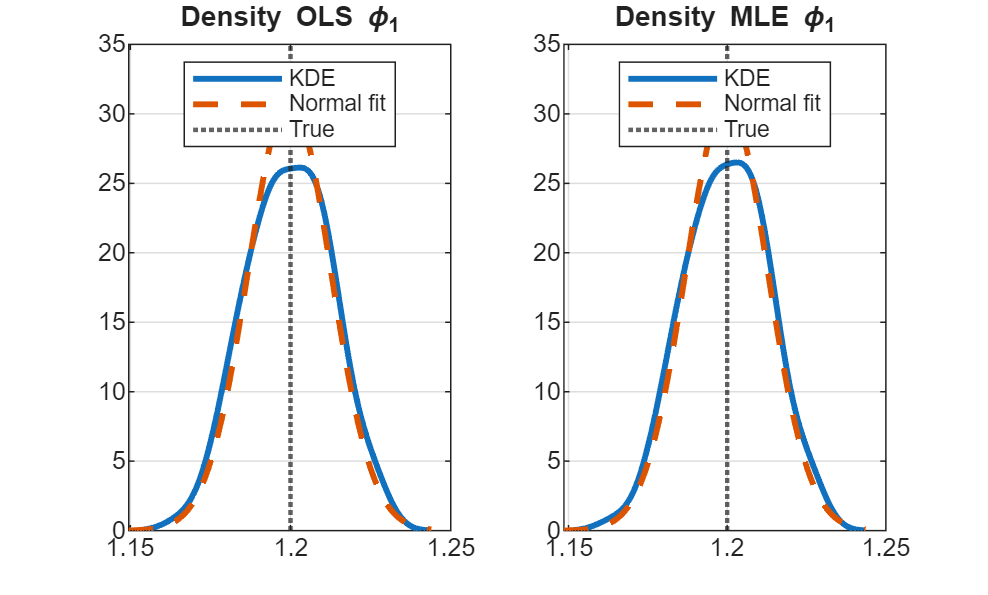


%% Densities
figure;
subplot(1,2,1)
[fo,xo]=ksdensity(MCest_OLS(:,ip)); plot(xo,fo,'LineWidth',2); hold on
mu_o=mean(MCest_OLS(:,ip),'omitnan'); sd_o=std(MCest_OLS(:,ip),'omitnan');
plot(xo,normpdf(xo,mu_o,sd_o),'--','LineWidth',2); xline(arp(ip),':','LineWidth',1.5);
title(sprintf('Density OLS \\phi_%d',ip)); legend('KDE','Normal fit','True','Location','best'); grid on

subplot(1,2,2)
[fm,xm]=ksdensity(MCest_MLE(:,ip)); plot(xm,fm,'LineWidth',2); hold on
mu_m=mean(MCest_MLE(:,ip),'omitnan'); sd_m=std(MCest_MLE(:,ip),'omitnan');
plot(xm,normpdf(xm,mu_m,sd_m),'--','LineWidth',2); xline(arp(ip),':','LineWidth',1.5);
title(sprintf('Density MLE \\phi_%d',ip)); legend('KDE','Normal fit','True','Location','best'); grid on

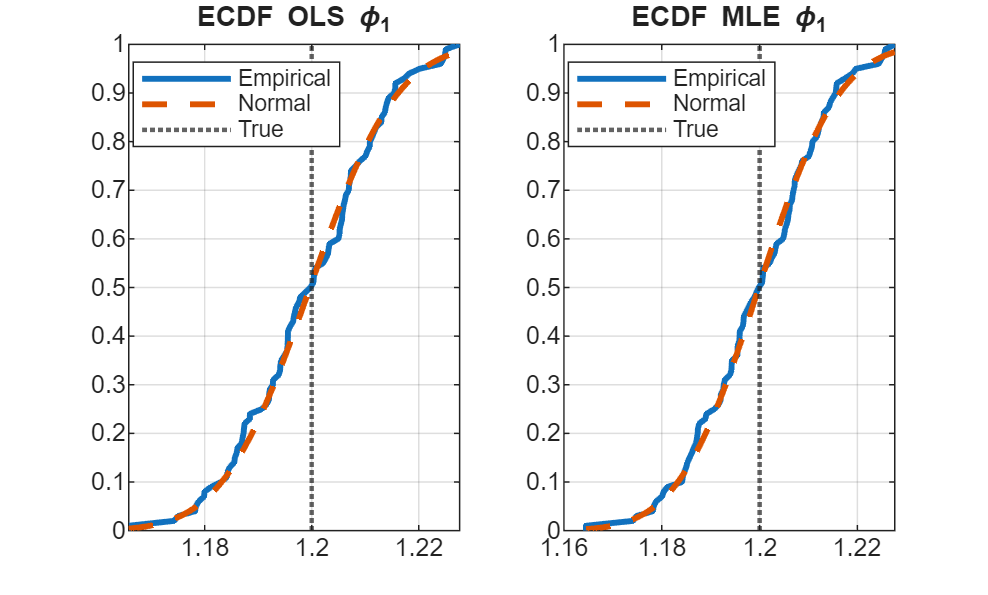


%% ECDFs
figure;
subplot(1,2,1)
[Fo,Xo]=ecdf(MCest_OLS(:,ip)); plot(Xo,Fo,'LineWidth',2); hold on
xx = linspace(min(Xo),max(Xo),200);
plot(xx,normcdf(xx,mu_o,sd_o),'--','LineWidth',2); xline(arp(ip),':','LineWidth',1.5);
title(sprintf('ECDF OLS \\phi_%d',ip)); legend('Empirical','Normal','True','Location','best'); grid on

subplot(1,2,2)
[Fm,Xm]=ecdf(MCest_MLE(:,ip)); plot(Xm,Fm,'LineWidth',2); hold on
xx = linspace(min(Xm),max(Xm),200);
plot(xx,normcdf(xx,mu_m,sd_m),'--','LineWidth',2); xline(arp(ip),':','LineWidth',1.5);
title(sprintf('ECDF MLE \\phi_%d',ip)); legend('Empirical','Normal','True','Location','best'); grid on


%% Monte Carlo statistics: bias and 95% quantile CIs
bias_OLS = mean(MCest_OLS,1,'omitnan') - arp;
bias_MLE = mean(MCest_MLE,1,'omitnan') - arp;

CI_OLS = quantile(MCest_OLS,[0.025 0.975]);     % 2-by-p
CI_MLE = quantile(MCest_MLE,[0.025 0.975]);     % 2-by-p

fprintf('\nBias OLS (phi_1..phi_p):\n'); disp(bias_OLS);


Bias OLS (phi_1..phi_p):
   1.0e-03 *

   -0.3257    0.0930   -0.1274   -0.3079    0.3384



fprintf('Bias MLE (phi_1..phi_p):\n'); disp(bias_MLE);

Bias MLE (phi_1..phi_p):
   1.0e-03 *

   -0.1597    0.0500   -0.4473    0.1044    0.0722




fprintf('95%% CI OLS (rows: [2.5%%;97.5%%]):\n'); disp(CI_OLS);

95% CI OLS (rows: [2.5%;97.5%]):
    1.1750   -0.5423   -0.3380    0.3528   -0.2260
    1.2249   -0.4573   -0.2565    0.4448   -0.1710



fprintf('95%% CI MLE (rows: [2.5%%;97.5%%]):\n'); disp(CI_MLE);

95% CI MLE (rows: [2.5%;97.5%]):
    1.1748   -0.5421   -0.3383    0.3538   -0.2262
    1.2255   -0.4572   -0.2568    0.4451   -0.1710




%% ---------- Helper functions ----------
function y = simulate_ar(phi, sigma2, T, B)
% Simulate AR(p): y_t = sum_{k=1}^p phi_k y_{t-k} + eps_t, eps~N(0,sigma2)
    if nargin<4, B = 500; end
    p = numel(phi);
    e = sqrt(sigma2)*randn(T+B,1);
    y = zeros(T+B,1);
    for t = (p+1):(T+B)
        y(t) = phi * flipud(y(t-p:t-1)) + e(t);
    end
    y = y(B+1:end);
end

function phi_hat = ar_ols_phi_only(y, p)
% Conditional least squares without intercept (like ar(..., method="ols"))
    T = numel(y);
    Y = y((p+1):T);
    X = zeros(T-p, p);
    for k = 1:p
        X(:,k) = y((p+1-k):(T-k));
    end
    phi_hat = X \ Y;         % p-by-1
    phi_hat = phi_hat(:).';  % 1-by-p
end


For an autoregressive process of order p,


$$\[
y_t - \sum_{i=1}^{p} \phi_i \, y_{t-i} = \varepsilon_t,
\]$$


stationarity requires that all the roots of the characteristic polynomial


$$\[
1 - \phi_1 z - \phi_2 z^2 - \cdots - \phi_p z^p = 0
\]$$


lie outside the unit circle, that is, $\(|z| > 1\$).

In our case, the AR(5) coefficients


$$\[
[\phi_1, \phi_2, \phi_3, \phi_4, \phi_5] =
[1.2,\,-0.5,\,-0.3,\,0.4,\,-0.2]
\]$$


violate this condition. Consequently, the process is non-stationary, and the

Gaussian maximum likelihood estimator (MLE) may fail to converge or behave

erratically, while the ordinary least squares (OLS) estimator will also be

unreliable and inconsistent.

In this Monte Carlo experiment, we investigated the sampling distribution of the

OLS and MLE estimators for several autoregressive models, including a non-stationary

AR(5) process. In the stationary cases (e.g., AR(1) and AR(3)), both estimators

perform well: their sampling distributions are approximately normal and centered

close to the true parameter values, with small bias and variability decreasing as

sample size increases.

For the AR(5) model, however, the process is non-stationary, as at least one root

of the characteristic polynomial lies on or inside the unit circle. In this case

the underlying assumptions of both OLS and MLE estimation are violated.

Consequently, the estimators become unstable: the estimated coefficients show high

variance, the MLE procedure may fail to converge, and the resulting empirical

distributions are often distorted and biased.

This comparison highlights that both OLS and MLE rely on the stationarity of the

data-generating process. When the AR process is stationary, the two estimators

produce very similar results (MLE being slightly more efficient under normal

errors). When the process is non-stationary, neither estimator is consistent, and

the Monte Carlo results illustrate the breakdown of standard asymptotic inference.